% Convert into Hex [LSB MSB].
HexLSN = HexPacket1(4,:);
    LSN = hex2dec(HexLSN);

HexFSA = strcat(HexPacket1(6,:), HexPacket1(5,:));
    FSA = hex2dec(HexFSA);

HexLSA = strcat(HexPacket1(8,:), HexPacket1(7,:));
    LSA = hex2dec(HexLSA);

%Calculate the Angles
AngleFSA = bitshift(FSA,-1)/64;
AngleLSA = bitshift(LSA,-1)/64;
diffAngle = AngleLSA - AngleFSA;

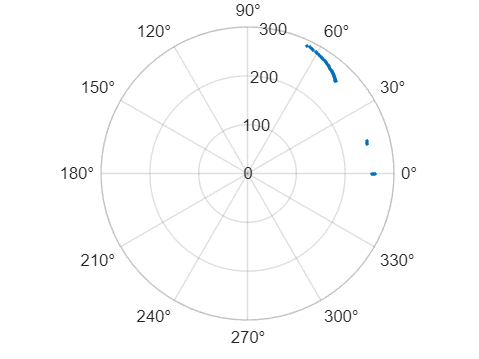

HexSi = HexPacket1(11:end,:);
% Mirror and Combine "MSBLSB".
DistHex = strings(size(HexSi, 1) / 2, 1);
for i = 1:2:length(HexSi)
    DistHex((i+1)/2) = strcat(HexSi(i+1,:), HexSi(i,:));
end

AngleSi(LSN) = AngleFSA;
for i = 2:LSN-1
    AngleSi(i) = (diffAngle/(LSN-1))*(i - 1)+AngleFSA;
end
AngleSi(end) = AngleLSA;
AngleSi = AngleSi';
Si = hex2dec(DistHex);
%The unit is meter
Si = Si/4000; 
polarplot(Si,AngleSi,'.');